%3.1
% s = [3 2 -1 0 -1 2]'
% o = [1 1 1 1 1 1]' 
% n = 0:5
% v1 = exp(j*(pi/3).*n)'
% v2 = conj(v1)
% v = [o v1 v2]
% sappx = v*(inv(v'*v))*v'*s
% checkorth = sappx - s
% dot(o, checkorth)
% p1 = (dot(s, o)./(norm(o)*norm(o))).*o %dot(o, o) == (norm(o)*norm(o))
% p2 = (dot(s, v1)./(norm(v1)*norm(v1))).*v1
% p3 = (dot(s, v2)./(norm(v2)*norm(v2))).*v2
% sum = p1 + p2 + p3
% %check
% checkorth = sum - s
% dot(o, checkorth)
% dot(v1, checkorth)
% dot(v2, checkorth)
% squaredappxerror = dot(sappx - s, sappx - s)

%3.2
% s = [4 3 2 1 0 1 2 3]'
% o = [1 1 1 1 1 1 1 1]' 
% n = 0:7
% v1 = exp(j*(pi/4).*n)'
% v2 = exp(j*(7*pi/4).*n)'
% v = [o v1 v2]
% sappx = v*(inv(v'*v))*v'*s
% p1 = (dot(s, o)./(norm(o)*norm(o))).*o %dot(o, o) == (norm(o)*norm(o))
% p2 = (dot(s, v1)./(norm(v1)*norm(v1))).*v1
% p3 = (dot(s, v2)./(norm(v2)*norm(v2))).*v2
% sum = p1 + p2 + p3
% squaredappxerror = dot(sappx - s, sappx - s)

%3.3
% s = [2*sqrt(2) - 1, 1, -2*sqrt(2) - 1, 5, -2*sqrt(2) - 1, 1, 2*sqrt(2) - 1, -3]'
% n = 0:7
% k = (0:7)'
% v = exp(j*(pi/4).*k.*n)
% S = conj(v)*s
% magS = abs(S)
% angleS = angle(S) %?

%3.4
% s = [1 4 -2 5]'
% n = 0:3
% k = (0:3)'
% v = exp(j*(pi/2).*k.*n)
% c = (inv(v'*v))*v'*s
% lincomb = v*c

%3.5

%3.6
% x = [0 0 1 0 1 0]'
% n = 0:5;
% y = cos(2*pi*n/3)'
% k = (0:5)';
% v = exp(j*(pi/3).*k.*n);
% eulers = (v(:,3) + v(:, 5))/2; %real cos(2*pi*n/3) == v(2*pi*2/6) + v(2*pi*(6-2)/6) conjugate symmetry
% check = y - eulers;
% X = conj(v)*x
% Y = conj(v)*y

%3.7
% X = [4, 1+j, 3-j, 3+j, 1-j]'
% magX = abs(X)
% angleX = angle(X)
% N = 5
% n = 0:4;
% k = (0:4)';
% v = exp(j*(2*pi/5).*k.*n);
% xform = (1/N)*v*X
% x = X(1)/5 + (2/5)*( abs(X(2))*cos((2*pi*n/5) + angle(X(2))) + abs(X(3))*cos((4*pi*n/5) + angle(X(3))))'

%3.8
% n = 0:7;
% k = (0:7)';
% v = exp(j*(2*pi/8).*k.*n)
% x = (3*(-1).^n + 7*cos(pi.*n/4 + 1.2) + 2*cos(pi.*n/2 -.8))'
% X = v'*x

%3.9
% N=16;
% r = 0.7;
% n=(0:N-1)';
% x = r.^n;
% A = abs(fft(x))
% bar(n,A.^2)
% squareamplitudespectrum = (.9933644582)./(1.49 - 1.4*cos(2*pi.*n/16))

%3.10
% x = [2 1 -1 -2 -3 3]'
% I = eye(6);
% Q = flip(I)
% P1 = circshift(I,1);
% P5 = circshift(I,5);
% R = P1*Q
% n = 0:5;
% k = (0:5)';
% v = exp(j*(2*pi/6).*k.*n)
% x1 = P1*x
% x2 = P5*x
% x3 = P1*x + P5*x
% x4 = x + R*x
% x5 = x - R*x
% x6 = v(:, 4).*x
% x7 = (I - v(:, 4))*x

%3.11

%3.12

%3.13

%3.14

%3.15

%3.16
% n = (0:63)';
% X =[ones(11,1); zeros(43,1); ones(10,1)];
% plot(ifft(X))
% bar(X), axis tight
% max(imag(ifft(X))) % See (i) below
% x = real(ifft(X));
% bar(x)
% cs = cos(3*pi*n/4); % See (ii) below yes n = 24
% y = x.*cs;
% plot(y)
% bar(y);
% max(imag(fft(y))) % See (iii) below
% Y = real(fft(y));
% bar(Y) % See (iv) below

%3.17

%3.18
% x = [1 2 3 4]'
% y = [5 6 7 8]'
% I = eye(4);
% P1 = circshift(I,1);
% P2 = circshift(I,2);
% P3 = circshift(I,3);
% Q = flip(I);
% R = P1*Q;
% s0 = dot(x, (R*y))
% s1 = dot(x, (P1*R*y))
% s2 = dot(x, (P2*R*y))
% s3 = dot(x, (P3*R*y))
% ccirc = ifft(fft(x).*fft(y))
% R*y
% M = [(R*x) (P1*R*x) (P2*R*x) (P3*R*x)]'
% s = M*y
%check with DFT
% S = fft(x) .* fft(y)
% n = 0:3;
% k = (0:3)';
% v = exp(j*(2*pi/4).*k.*n)
% s = (1/4)*v*S
% For the circular convolution of x and y to be equivalent, you must pad the vectors with zeros to length at least N + L - 1 before you take the DFT. After you invert the product of the DFTs, retain only the first N + L - 1 elements.
% Create two vectors, x and y, and compute the linear convolution of the two vectors.
% x = [2 1 2 1];
% y = [1 2 3];
% clin = conv(x,y);
% The output has length 4+3-1.
% Pad both vectors with zeros to length 4+3-1. Obtain the DFT of both vectors, multiply the DFTs, and obtain the inverse DFT of the product.
% xpad = [x zeros(1,6-length(x))];
% ypad = [y zeros(1,6-length(y))];
% ccirc = ifft(fft(xpad).*fft(ypad));
% The circular convolution of the zero-padded vectors, xpad and ypad, is equivalent to the linear convolution of x and y. You retain all the elements of ccirc because the output has length 4+3-1.

%3.19
% X = [1 2 3 4]'
% Y = [5 6 7 8]'
% S = (1/4)*ifft(fft(X).*fft(Y))

%3.20
% X = [1 0 1 -1]'
% Y = [3 5 8 -4]'
% S1 = (1/4)*ifft(fft(X).*fft(Y))
% S2 = X.*Y

%3.21
% n = 0:3;
% k = (0:3)';
% v = exp(j*(2*pi/4).*k.*n)
% x = [2 0 1 3]'
% y = [1 -1 2 -4]'
% X = fft(x)
% Y = fft(y)
% S = (1/4)*ifft(fft(x).*fft(v(:,3).*y))

%3.22
% y = [1 + j, 2, 1 - j, 0]'
% I = eye(4);
% P1 = circshift(I,1);
% P2 = circshift(I,2);
% P3 = circshift(I,3);
% Q = flip(I);
% R = P1*Q;
% s = (1/4)*ifft(fft(y).*fft(R.*conj(y))) % i think this circular
% convolution is the problem could 

%3.23

%3.24
% x = [1 -1 1 -1]'
% X = fft(x)
% x = [1 -1 1 -1 0 0 0 0]'
% X = fft(x)

%3.25

%3.26

%3.27

%3.28

%3.29
% x = [0 0 0 0 0 0 0 126 0 0 0 84 0 0 0 0 0 0 0 0 0 84 0 0 0  126 0 0 0 0 0 0]'

%3.30

%3.31

%3.32
f = 330

f = 330

fs = 46200

fs = 46200

n = 0:2309;
x = cos((2*pi*f/fs)*n)

x =     1.0000    0.9990    0.9960    0.9909    0.9839    0.9749    0.9640    0.9511    0.9362    0.9195    0.9010    0.8806    0.8584    0.8346    0.8090    0.7818    0.7531    0.7228    0.6911    0.6579    0.6235    0.5878    0.5509    0.5129    0.4739    0.4339    0.3930    0.3514    0.3090    0.2660    0.2225    0.1786    0.1342    0.0896    0.0449    0.0000   -0.0449   -0.0896   -0.1342   -0.1786   -0.2225   -0.2660   -0.3090   -0.3514   -0.3930   -0.4339   -0.4739   -0.5129   -0.5509   -0.5878


n2 = 0:139;
x2 = cos((2*pi*f/fs)*n2)

x2 =     1.0000    0.9990    0.9960    0.9909    0.9839    0.9749    0.9640    0.9511    0.9362    0.9195    0.9010    0.8806    0.8584    0.8346    0.8090    0.7818    0.7531    0.7228    0.6911    0.6579    0.6235    0.5878    0.5509    0.5129    0.4739    0.4339    0.3930    0.3514    0.3090    0.2660    0.2225    0.1786    0.1342    0.0896    0.0449    0.0000   -0.0449   -0.0896   -0.1342   -0.1786   -0.2225   -0.2660   -0.3090   -0.3514   -0.3930   -0.4339   -0.4739   -0.5129   -0.5509   -0.5878


xs = x(1:140)

xs =     1.0000    0.9990    0.9960    0.9909    0.9839    0.9749    0.9640    0.9511    0.9362    0.9195    0.9010    0.8806    0.8584    0.8346    0.8090    0.7818    0.7531    0.7228    0.6911    0.6579    0.6235    0.5878    0.5509    0.5129    0.4739    0.4339    0.3930    0.3514    0.3090    0.2660    0.2225    0.1786    0.1342    0.0896    0.0449    0.0000   -0.0449   -0.0896   -0.1342   -0.1786   -0.2225   -0.2660   -0.3090   -0.3514   -0.3930   -0.4339   -0.4739   -0.5129   -0.5509   -0.5878


X = fft(xs)

X =   -0.0000 + 0.0000i  70.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i


absX = abs(X)

absX =     0.0000   70.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


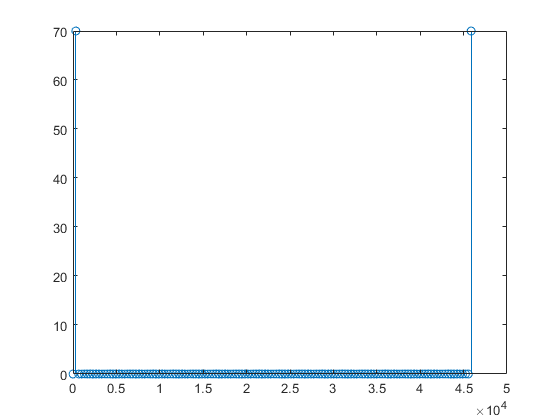

r1 = (0:139)*(fs/140);
stem(r1, absX)